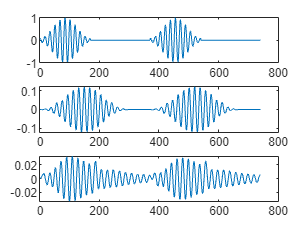

pulsbreite = 170; % in Samples
freq = 475; %  in Hertz (400)
fa=8000; % in Hertz

k=0:(pulsbreite-1);
hf=cos(2*pi*freq/fa*k);
lf=hamming(pulsbreite); % alternativ gausswin
puls=hf.*lf';

x = [puls zeros(1,200) puls zeros(1,200) ];

y_fir = filter(hd_fir,x);
y_iir = filter(hd_iir,x);

subplot(3,1,1)
plot(x)
subplot(3,1,2)
plot(y_fir)
subplot(3,1,3)
plot(y_iir)